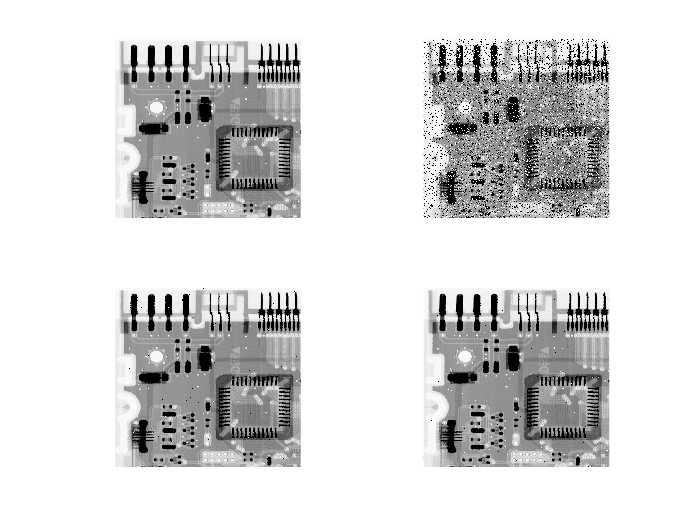

clear;clc;
f=imread("Fig0219(a).tif");
fn=imnoise(f,'salt & pepper',0.2);%附加椒盐噪音
gm=medfilt2(fn);%对带噪音图像进行中值滤波处理
gms=medfilt2(fn,'symmetric');%指出原图像按照镜面反射方式对称地沿边缘扩展。
figure;
subplot(2,2,1);imshow(f);
subplot(2,2,2);imshow(fn);
subplot(2,2,3);imshow(gm);
subplot(2,2,4);imshow(gms);